n0=linspace(0.01,0.99,99)

n0 =    0.010000000000000   0.020000000000000   0.030000000000000   0.040000000000000   0.050000000000000   0.060000000000000   0.070000000000000   0.080000000000000   0.090000000000000   0.100000000000000   0.110000000000000   0.120000000000000   0.130000000000000   0.140000000000000   0.150000000000000   0.160000000000000   0.170000000000000   0.180000000000000   0.190000000000000   0.200000000000000   0.210000000000000   0.220000000000000   0.230000000000000   0.240000000000000   0.250000000000000   0.260000000000000   0.270000000000000   0.280000000000000   0.290000000000000   0.300000000000000   0.310000000000000   0.320000000000000   0.330000000000000   0.340000000000000   0.350000000000000   0.360000000000000   0.370000000000000   0.380000000000000   0.390000000000000   0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.490000000000000   0.5000000000

W111P=zeros(99,1);
GHZP=zeros(99,1);
for i=1:99
    n=n0(i);
    if n<=2*sqrt(2)/3
        y=(1/2)*sqrt(3)*sqrt(1-sqrt(1-n^2));
    else 
        y=-(1/2)*sqrt(3)*sqrt(1+sqrt(1-n^2));
    end
    W111P(i)=De2P(0,y,sqrt(1-y^2),"Negativity");
    x=sqrt(1-sqrt(1-n^2))/sqrt(2);
    GHZP(i)=De2P(x,0,sqrt(1-x^2),"Negativity");
end
W111P

W111P =    0.009852577174634
   0.019420249024407
   0.028717142534506
   0.037756414708168
   0.046550337543673
   0.055110374031197
   0.063447246274620
   0.071570996688907
   0.079491043093525
   0.087216228411865


GHZP

GHZP =    0.053790007163011
   0.081575061178529
   0.103053677637236
   0.120975550512525
   0.136506495131552
   0.150281261565891
   0.162693957561401
   0.174010339258925
   0.184420146658485
   0.194064661142532


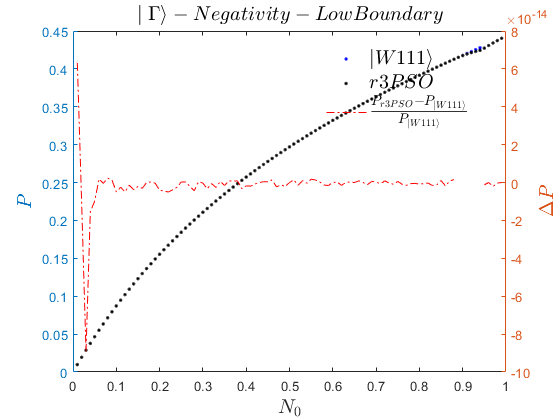

figure
yyaxis left
plot(GDedata2PSO(:,1),W111P(:),"b.")
hold on
plot(GDedata2PSO(:,1),GDedata2PSO(:,5),"k.")
ylabel("$P$","Interpreter","latex","FontSize",15)
yyaxis right
plot(GDedata2PSO(1:88,1),(GDedata2PSO(1:88,5)-W111P(1:88))./W111P(1:88),"r-.")
plot(GDedata2PSO(95:end,1),(GDedata2PSO(95:end,5)-W111P(95:end))./W111P(95:end),"r-.")
ylabel("$\Delta P$","Interpreter","latex","FontSize",15)
xlabel("$N_0$","Interpreter","latex","FontSize",15)
legend('boxoff')
legend("$|W111\rangle$","$r3PSO$","$\frac{P_{r3PSO}-P_{|W111\rangle}}{P_{|W111\rangle}}$","Interpreter","latex","FontSize",15,"Location","best")
title(strcat("$","\mid \Gamma \rangle-","Negativity","-","Low","Boundary","$"),"Interpreter","latex","FontSize",15)

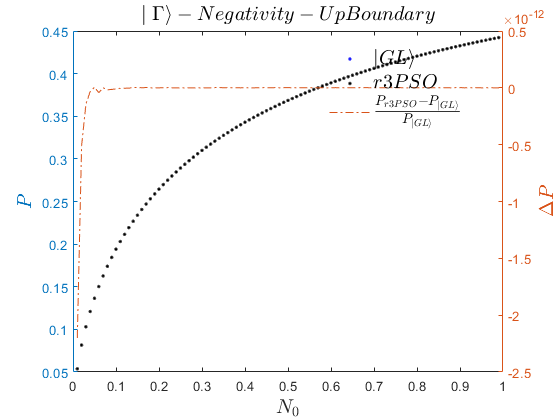

%--------------------------------------------
figure
yyaxis left
plot(n0,GHZP,"b.")
hold on
plot(GDedata1PSO(:,1),GDedata1PSO(:,5),"k.")
ylabel("$P$","Interpreter","latex","FontSize",15)
yyaxis right
plot(GDedata1PSO(:,1),(GDedata1PSO(:,5)-GHZP(:))./GHZP(:),"-.")
ylabel("$\Delta P$","Interpreter","latex","FontSize",15)
xlabel("$N_0$","Interpreter","latex","FontSize",15)
legend('boxoff')
legend("$|GL\rangle$","$r3PSO$","$\frac{P_{r3PSO}-P_{|GL\rangle}}{P_{|GL\rangle}}$","Interpreter","latex","FontSize",15,"Location","best")
title(strcat("$","\mid \Gamma \rangle-","Negativity","-","Up","Boundary","$"),"Interpreter","latex","FontSize",15)

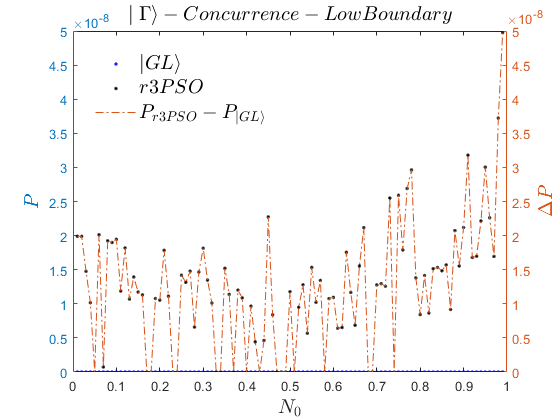


figure
yyaxis left
plot(n0,zeros(99,1),"b.")
hold on
plot(GDedata22PSO(:,1),GDedata22PSO(:,5),"k.")
ylabel("$P$","Interpreter","latex","FontSize",15)
yyaxis right
plot(GDedata22PSO(:,1),(GDedata22PSO(:,5)-0),"-.")
ylabel("$\Delta P$","Interpreter","latex","FontSize",15)
xlabel("$N_0$","Interpreter","latex","FontSize",15)
legend('boxoff')
legend("$|GL\rangle$","$r3PSO$","$P_{r3PSO}-P_{|GL\rangle}$","Interpreter","latex","FontSize",15,"Location","best")
title(strcat("$","\mid \Gamma \rangle-","Concurrence","-","Low","Boundary","$"),"Interpreter","latex","FontSize",15)